clear 
clc

% ---------------------------------------------------------
% Transmitter
% 
% SS-watermerking of bitstream
% ---------------------------------------------------------

% Define the key for spreading the watermark
key = hadamard(32);
key = (key(5,:)+1)/2;

% Define the bitstream to be embedded
bitstream = [1, 0, 1, 1, 0, 0, 1, 1, 1, 0, 1, 0, 0, 1, 1, 0, ...             
    1, 1, 0, 0, 1, 0, 1, 1, 0, 1, 1, 0, 0, 1, 0, 1 ...             
    1, 0, 1, 1, 0, 0, 1, 1, 1, 0, 1, 0, 0, 1, 1, 0, ...             
    1, 1, 0, 0, 1, 0, 1, 1, 0, 1, 1, 0, 0, 1, 0, 1];

% Define the bits of the watermark to be embedded
%watermark_bits = [1, 0, 1, 0];
watermark_bits = [1, 0];

% Spread the watermark bits using the key
watermark_spread = zeros(1, length(bitstream));
for i = 1:length(watermark_bits)
    watermark_bit = watermark_bits(i);
    idx = (i-1)*length(key)+1:i*length(key);
    watermark_spread(idx) = key * watermark_bit;
end

% Embed the watermark into the bitstream
alpha = 1; % Strength of watermark
watermarked_bitstream = bitstream + alpha * watermark_spread;

% ---------------------------------------------------------
% Channel
% 
% AWAGN
% ---------------------------------------------------------

% Define the SNR
SNR = 25; 

% Add AWGN to the watermarked signal
watermarked_bitstream_noisy = wagn(watermarked_bitstream, SNR, 'measured');

% ---------------------------------------------------------
% Intentional interference that destroys 2 bits
% 
% Jamming
% ---------------------------------------------------------

% Generate jamming signal that destroys 2 bits
jamming_signal = zeros(size(watermarked_bitstream_noisy));
jamming_signal(1) =  randi([0,1],1); % Destroy XX bits

% Add jamming signal to the watermarked signal
watermarked_bitstream_jammed = watermarked_bitstream_noisy + jamming_signal;

% ---------------------------------------------------------
% Receiver
% 
% Despreading to receover the watermark and the bitstream
% ---------------------------------------------------------

% Despread and extract the watermark bits from the watermarked bitstream
extracted_watermark_bits = zeros(1, length(watermark_bits));
correlation = zeros(1, length(watermark_bits));
for i = 1:length(watermark_bits)
    watermark_bit = watermark_bits(i);
    idx = (i-1)*length(key)+1:i*length(key);
    correlation(i) = dot(watermarked_bitstream_jammed(idx), key);
end

th_corr = 0.7 * max(correlation);

for i = 1:length(watermark_bits)
    extracted_watermark_bits(i) = (correlation(i) > th_corr);
end


% ---------------------------------------------------------
% Plot
% 
% Graphs
% ---------------------------------------------------------
% Compute the FFT of the original bitstream
N = length(bitstream);
f = (0:N-1)/N;
bitstream_fft = fft(bitstream);
bitstream_fft_mag = abs(bitstream_fft);

% Compute the FFT of the watermarked signal
watermarked_fft = fft(watermarked_bitstream);
watermarked_fft_mag = abs(watermarked_fft);


% Compute the FFT of the watermarked signal
watermark_fft = fft(watermark_spread);
watermark_fft_mag = abs(watermark_fft);

% Compute the FFT of the watermarked signal
watermarked_noisy_fft = fft(watermarked_bitstream_noisy);
watermarked_noisy_fft_mag = abs(watermarked_bitstream_noisy);

% Compute the FFT of the watermarked signal
watermarked_j_fft = fft(watermarked_bitstream_jammed);
watermarked_j_fft_mag = abs(watermarked_bitstream_jammed);

% Verify that the extracted watermark bits match the original watermark bits
disp('Original watermark bits:')

Original watermark bits:


disp(watermark_bits)

     1     0



disp('Extracted watermark bits:')

Extracted watermark bits:


disp(extracted_watermark_bits)

     1     0



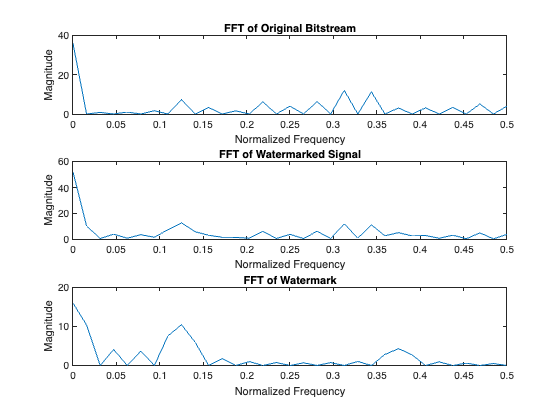


% Plot the original bitstream, the watermarked signal and the watermark
subplot(3,1,1)
plot(f, bitstream_fft_mag)
title('FFT of Original Bitstream')
xlabel('Normalized Frequency')
ylabel('Magnitude')
xlim([0 0.5])

subplot(3,1,2)
plot(f, watermarked_fft_mag)
title('FFT of Watermarked Signal')
xlabel('Normalized Frequency')
ylabel('Magnitude')
xlim([0 0.5])

% Plot the FFT of the watermark
subplot(3,1,3)
plot(f, watermark_fft_mag)
title('FFT of Watermark')
xlabel('Normalized Frequency')
ylabel('Magnitude')
xlim([0 0.5])

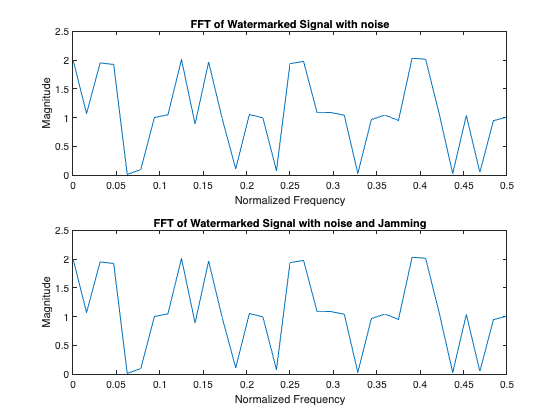


figure;
% Plot the FFT of the watermark
subplot(2,1,1)
plot(f, watermarked_noisy_fft_mag)
title('FFT of Watermarked Signal with noise')
xlabel('Normalized Frequency')
ylabel('Magnitude')
xlim([0 0.5])

% Plot the FFT of the watermark
subplot(2,1,2)
plot(f, watermarked_j_fft_mag)
title('FFT of Watermarked Signal with noise and Jamming')
xlabel('Normalized Frequency')
ylabel('Magnitude')
xlim([0 0.5])


% ---------------------------------------------------------
% Evaluation
% 
% Statistical indepencence tests to evaluate the correlation
% between the ss-wateramrk signal and the bitstream
% ---------------------------------------------------------

% First test
% Compute correlation coefficient
received_signal = watermark_spread;

corr_coeff = corrcoef(received_signal, bitstream);
corr_coeff = corr_coeff(1,2);

disp('First test: Compute correlation coefficient')

First test: Compute correlation coefficient


if corr_coeff < 0.1
    disp(['Correlation coefficient: ', num2str(corr_coeff)]);
    disp('The SS-WM and the bitstream are statistically independent')
else
    isp(['Correlation coefficient: ', num2str(corr_coeff)]);
    disp('The SS-WM and the bitstream are NOT statistically independent')

end

Correlation coefficient: 0


The SS-WM and the bitstream are statistically independent




% Second test
% Perform chi-squared test for independence
N = length(received_signal);
m1 = sum(received_signal);
m2 = sum(bitstream);

observed = [sum(received_signal & bitstream), sum(received_signal & ~bitstream); ...
            sum(~received_signal & bitstream), sum(~received_signal & ~bitstream)];

expected = [m1*m2/N, m1*(N-m2)/N; (N-m1)*m2/N, (N-m1)*(N-m2)/N];

chi2stat = sum(sum((observed - expected).^2 ./ expected));
pval = 1 - chi2cdf(chi2stat, 1);

disp('Second test: Perform chi-squared test for independence')

Second test: Perform chi-squared test for independence


if pval > 0.05
    disp(['Chi-squared test p-value: ', num2str(pval)]);
    disp('The SS-WM and the bitstream are statistically independent')
else
    disp(['Chi-squared test p-value: ', num2str(pval)]);
    disp('The SS-WM and the bitstream are NOT statistically independent')

end

Chi-squared test p-value: 1


The SS-WM and the bitstream are statistically independent
